# FINAL

## Longitudinal Coefficients of F4

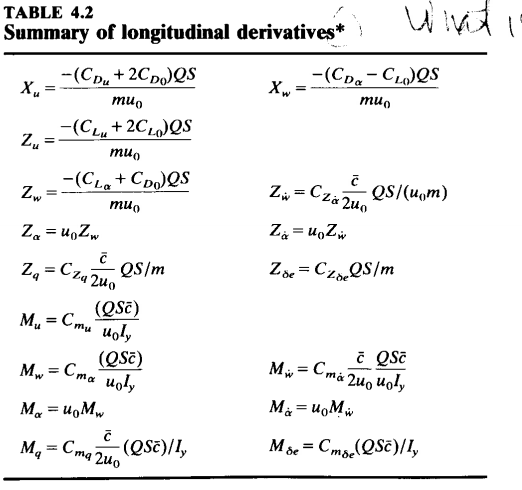

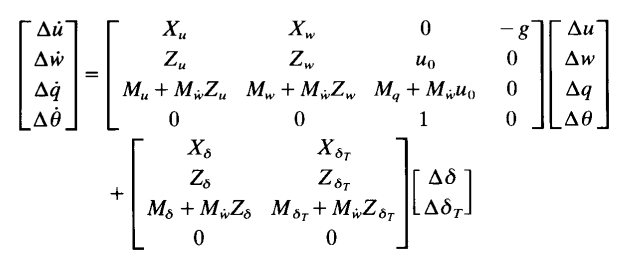

By using figures given above, the coefficients of the F4 Aircraft is given below.


Xu = -0.0122;
g0 = 32.086614;
Zu = -0.1105;
cmalfa = -0.4;
cmalfadot = -1.3;
Ix = 25000;
Iy = 122200;
Iz = 139800;
q = 283.2;
c = 16;
S = 530;
M = 0.9;
a = 982;
u0 = M*a;
mass = 39000;
cdalfa = 0.3;
clalfa = 3.75;
cmq = -2.7; 
clalfadot = 0.86;
cd0 = 0.0205;
rho = 0.000795;
% cmdelta = 
cl0 =  0.1;
Xw = (-(cdalfa - cl0)*q*S)/(mass*u0)

Xw = -8.7092e-04

Zw = (-(clalfa+cd0)*q*S)/(mass*u0)

Zw = -0.0164

Mu = -0.0026;
Mwdot = (cmalfadot*c^2*q*S)/(2*u0*u0*Iy)

Mwdot = -2.6166e-04

Mw = cmalfa*q*S*c/(u0*Iy)

Mw = -0.0089

Mq = -0.485;
X_deltae = 12.3976;
X_deltaT = 0;
cmdeltae = -0.58;
Mdelta_e = cmdeltae*q*S*c/Iy

Mdelta_e = -11.3985

Zdelta_e = -49.5906;
Mdelta_T = 0;
Z_deltaT = 0;
M_alpha = u0*Mw

M_alpha = -7.8610

theta = 2.6;

## Longitudinal Equation of Motion

 A = [Xu, Xw , 0, -g0*cosd(theta);
    Zu,Zw,u0,-g0*sind(theta);
    Mu+Mwdot*Zu,Mw+Mwdot*Zw,Mq+Mwdot*u0,-Mwdot*g0*sind(theta);
    0,0,1,0]

A =    -0.0122   -0.0009         0  -32.0536
   -0.1105   -0.0164  883.8000   -1.4555
   -0.0026   -0.0089   -0.7163    0.0004
         0         0    1.0000         0


B = [X_deltae,X_deltaT;
    Zdelta_e,Z_deltaT;
    Mdelta_e+Mwdot*Zdelta_e,Mdelta_T+Mwdot*Z_deltaT;
    0,0]

B =    12.3976         0
  -49.5906         0
  -11.3855         0
         0         0


C = [0,1,0,0;
    0,0,0,1];
D = [0,0;0,0];
sys = ss(A,B,C,D);
Long_sys = tf(sys)

Long_sys =
 
  From input 1 to output...
           -49.59 s^3 - 1.01e04 s^2 - 135.8 s - 35.99
   1:  --------------------------------------------------
       s^4 + 0.7449 s^3 + 7.877 s^2 - 0.00141 s + 0.02998
 
                -11.39 s^2 + 0.08316 s + 0.01574
   2:  --------------------------------------------------
       s^4 + 0.7449 s^3 + 7.877 s^2 - 0.00141 s + 0.02998
 
  From input 2 to output...
   1:  0
 
   2:  0
 
Continuous-time transfer function.



## Finding eigenvalues

[eigs] = eig(A)

eigs =   -0.3727 + 2.7812i
  -0.3727 - 2.7812i
   0.0003 + 0.0617i
   0.0003 - 0.0617i


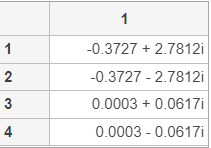

The eigenvalues of the system is given above. According to this figure, some of the roots of the characteristic equation are on the right half plane so the system unstable. As we learn from the lectures generally war planes are unstable.


$$\lambda_{short} = -0.3727 \pm 2.7812i$$



$$\lambda_{phugoid} = 0.0003 \pm 0.0617i$$


## Short Period Mode

zeta_sp = sqrt(1/(1+(2.7812/0.3727)^2))

zeta_sp = 0.1328

wn_sp = -(-0.3727/zeta_sp)

wn_sp = 2.8061

% rlocus(Long_sys(1,1));
% rlocus(Long_sys(2,1));


$$\zeta_{short} = 0.1328$$



$$\omega_{n_{short}} = 2.8061$$


## Short Period Approximations

s = tf('s');
A_short = [Zw u0;
   (Mw+Mwdot*Zw) (Mq+Mwdot*u0)];
wn_sp_appr = sqrt(Zw*Mq-u0*Mw)

wn_sp_appr = 2.8052

zet_sp_appr = -(Zw+Mq+u0*Mwdot)/(2*wn_sp_appr)

zet_sp_appr = 0.1306

G_sp_apprx = (wn_sp_appr^2)/(s^2+2*wn_sp_appr*zet_sp_appr*s+wn_sp_appr^2)

G_sp_apprx =
 
          7.869
  ----------------------
  s^2 + 0.7327 s + 7.869
 
Continuous-time transfer function.



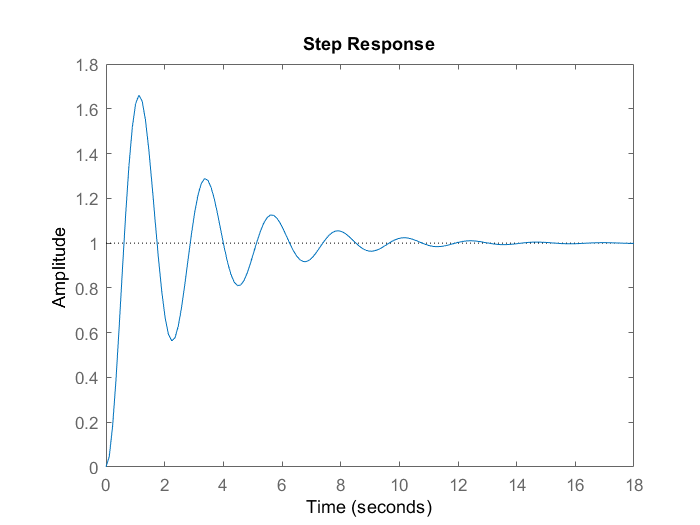

step(G_sp_apprx)

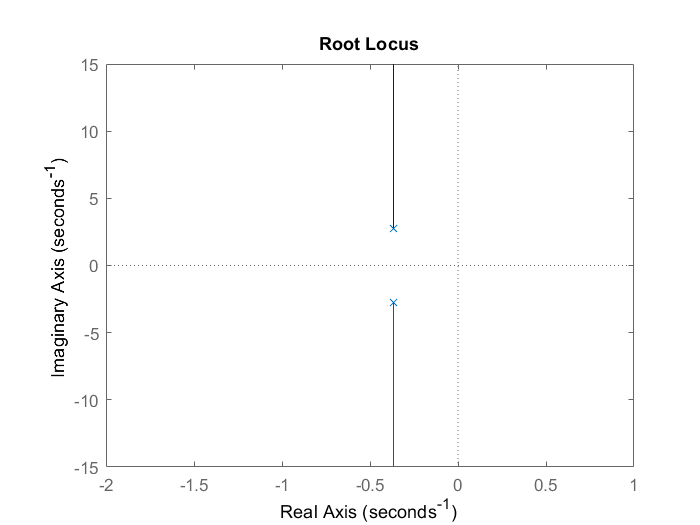

rlocus(G_sp_apprx)

## Phugoid Mode

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



zeta_ph = sqrt(1/(1+(0.0617/0.0003)^2))

zeta_ph = 0.0049

wn_ph = 0.0003/zeta_ph

wn_ph = 0.0617


$$\zeta_{phugoid} = 0.0049$$



$$\omega_{n_{phugoid}} = 0.0617$$


## Phugoid Mode Approximations

A_ph = [Xu -g0;
    -Zu/u0 0];
Wn_ph_appr = sqrt((-g0/u0)*Zu)

Wn_ph_appr = 0.0633

Zeta_ph_appr = -(Xu/(2*Wn_ph_appr))

Zeta_ph_appr = 0.0963

G_ph_appr = (Wn_ph_appr^2)/(s^2+2*Zeta_ph_appr*...
    Wn_ph_appr*s+Wn_ph_appr^2)

G_ph_appr =
 
          0.004012
  -------------------------
  s^2 + 0.0122 s + 0.004012
 
Continuous-time transfer function.



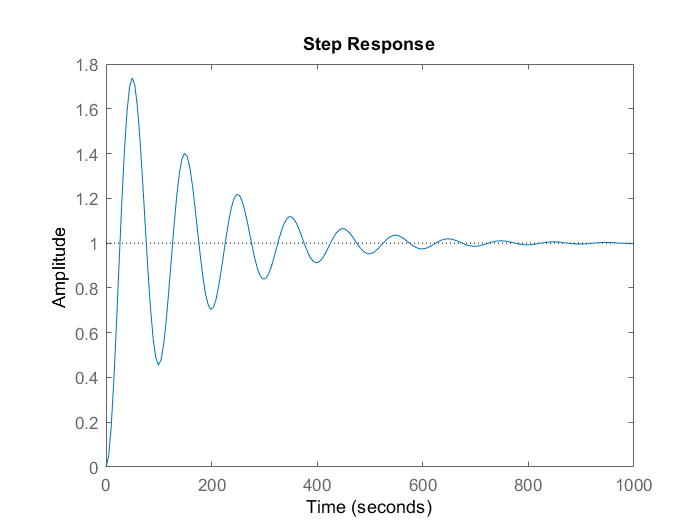

step(G_ph_appr)

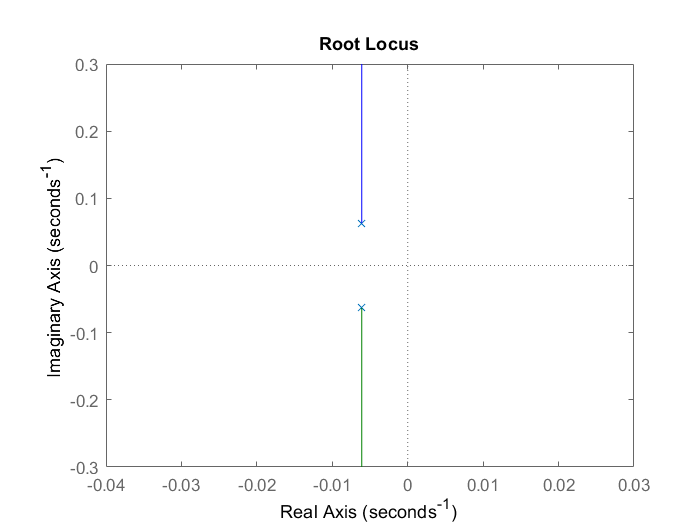

rlocus(G_ph_appr)

## Stability Augmentation System

## $\dot{\dot{\theta}} - (M_q + M_{\alpha})\dot{\theta}= M_{\delta}\delta$ The characteristic equation is:


$$\frac{\theta}{\delta_e}= \frac{M_{\delta}}{s^2-(M_q+M_{\alpha}s+M_{\alpha}}$$


$\rho$ on the 35000 ft equals to 0.000795


s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



G_pitc08 = Mdelta_e/(s^2-(Mq+M_alpha)*s+M_alpha)

G_pitc08 =
 
          -11.4
  ---------------------
  s^2 + 8.346 s - 7.861
 
Continuous-time transfer function.



sys_pitch = ss(G_pitc08);
A_pitch = sys_pitch.A;
B_pitch = sys_pitch.B;
if rank(ctrb(A_pitch,B_pitch)) == 2
    fprintf("The system is controllable.")
else
    fprintf("The system can not be control.")
end

The system is controllable.

As we see from the if block, the transfer function is  controllable. It has full rank.

## Without Stability Augmentation System

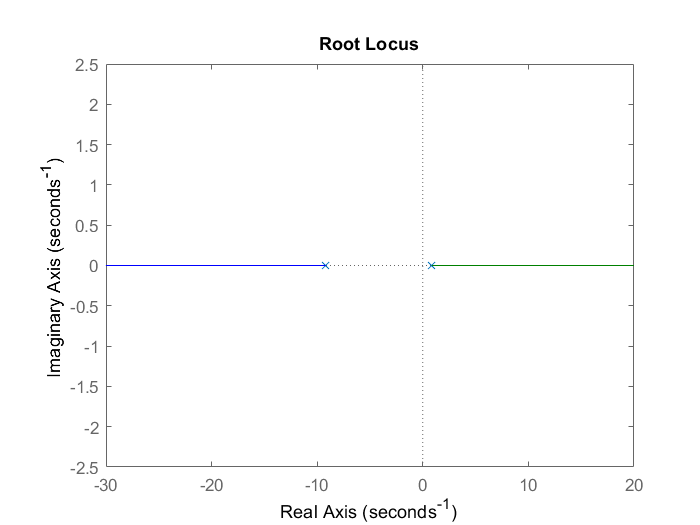

rlocus(G_pitc08);

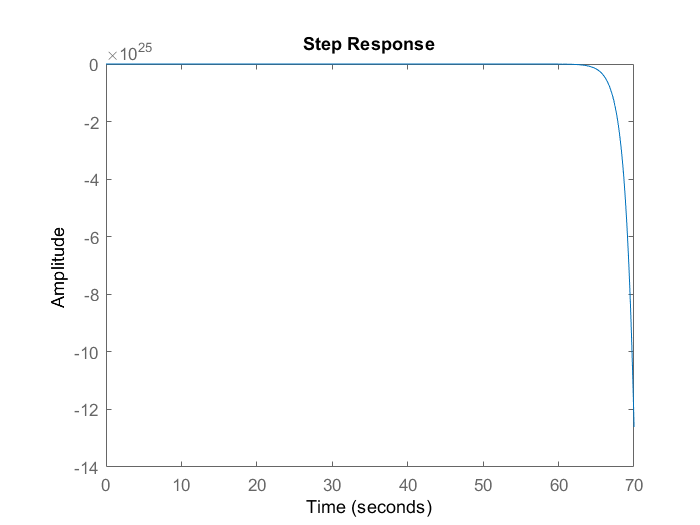

step(G_pitc08);

wn_sas = sqrt(-(cmalfa*u0^2*rho*S*c)/(2*Iy))

wn_sas = 2.9357

zeta_sas = (-(cmq+cmalfadot))*rho*u0*S*c^2/(8*wn_sas*Iy)

zeta_sas = 0.1329

As we see from the stability augmentation system, with rate gyro proportion,

 
$$\dot{\dot{\theta}}-(M_q+M_{\alpha}+K)\dot{\theta}+M_{\alpha}\theta=M_{\delta_e}\delta$$


we can arrange the roots of the characteristic equation by using K value.

## With Stability Augmentation System

K =4.19;
zeta_new =-(K+Mq+M_alpha)/(2*wn_sas)

zeta_new = 0.7078

G_sas = Mdelta_e/(s^2-(Mq+M_alpha+K)*s+M_alpha)

G_sas =
 
          -11.4
  ---------------------
  s^2 + 4.156 s - 7.861
 
Continuous-time transfer function.



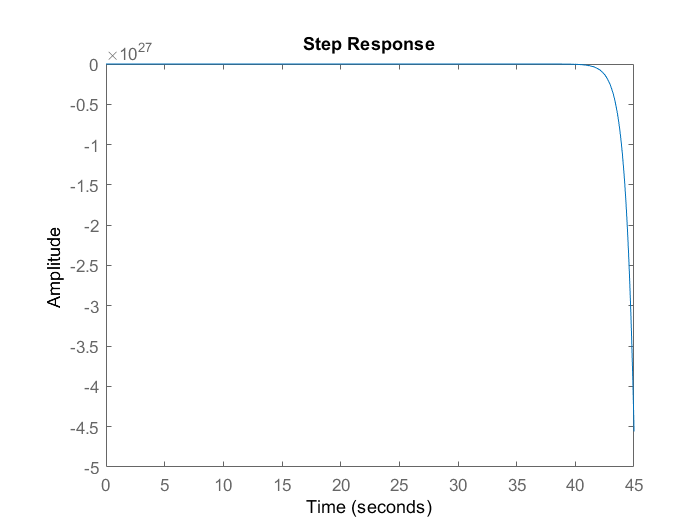

step(G_sas)

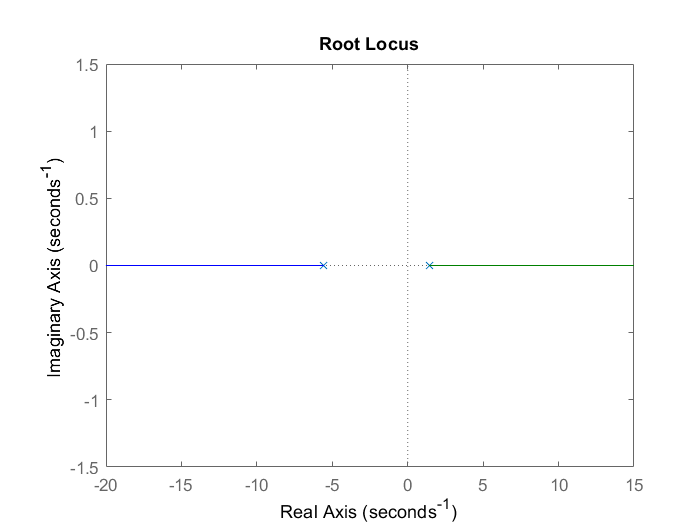

rlocus(G_sas)

## With PID Controller

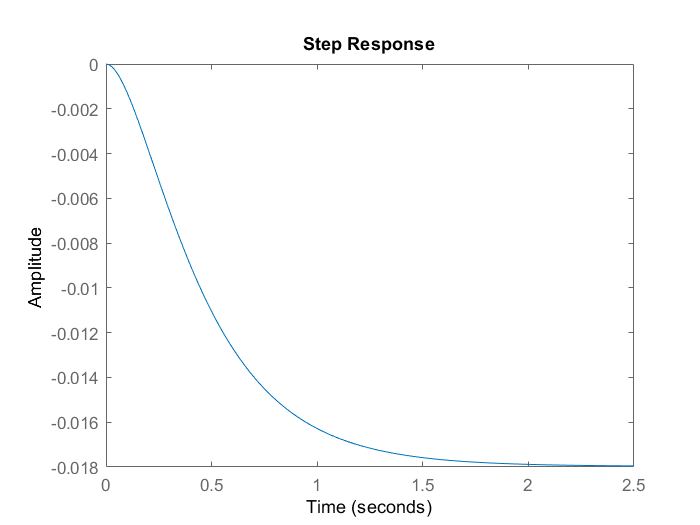


Kp = -303.327;
Ki = -642.116;
Kd = -31.836;
G_sas_pid = Mdelta_e/(s^2-(Mq+M_alpha+Kp+Ki/s+Kd*s)*s+M_alpha);
step(G_sas_pid);

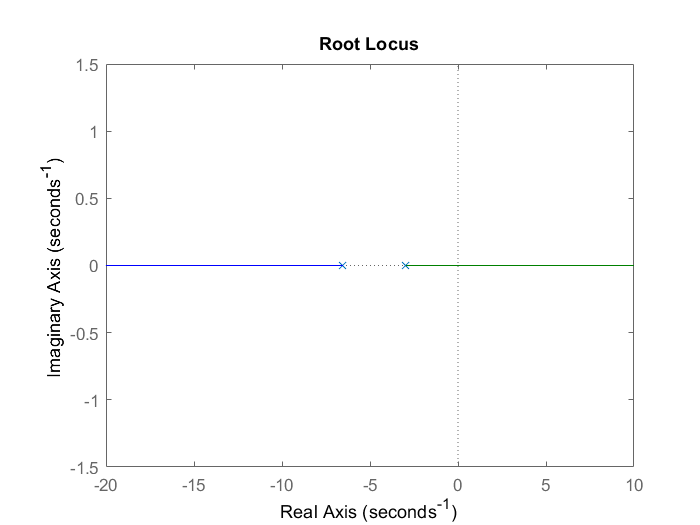

rlocus(G_sas_pid);

## With Pole Placement

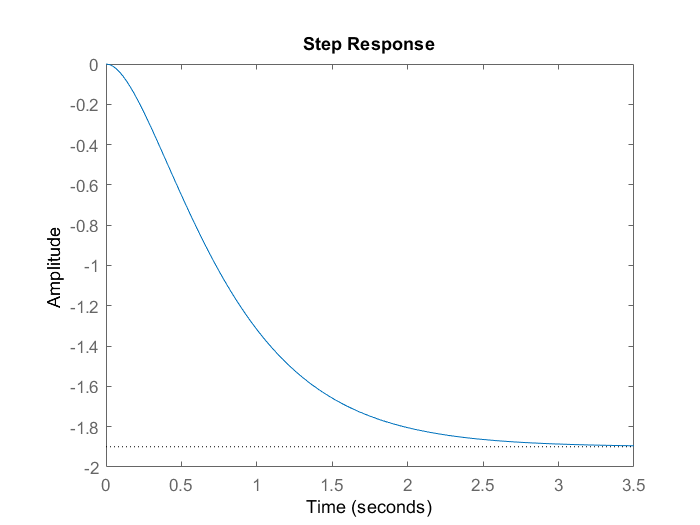


sys_sas = ss(G_sas);
A_sas = sys_sas.A;
B_sas = sys_sas.B;
C_sas =sys_sas.C;
D_sas = sys_sas.D;
new_pole = [-3,-2];
K = place(A_sas,B_sas,new_pole);
A_new = A_sas-B_sas.*K;
[num,den] = ss2tf(A_new,B_sas,C_sas,D_sas);
G_sas_last = tf(num,den);
step(G_sas_last)

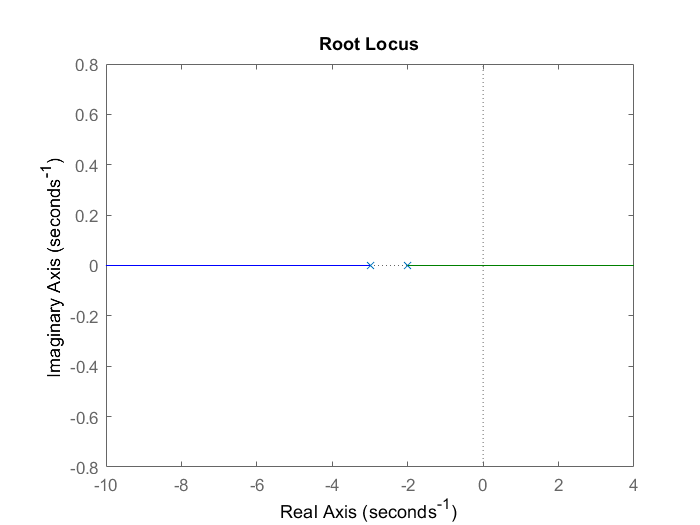

rlocus(G_sas_last)